# Concentration PID Control

The objective of this case study is to use an existing dynamic model of a blending tank and develop a controller to maintain outlet concentration. A mixing tank has a liquid inlet stream and outlet stream. The tank is well mixed so the concentration is assumed to be the same throughout the reactor. The temperature is not important for this application.

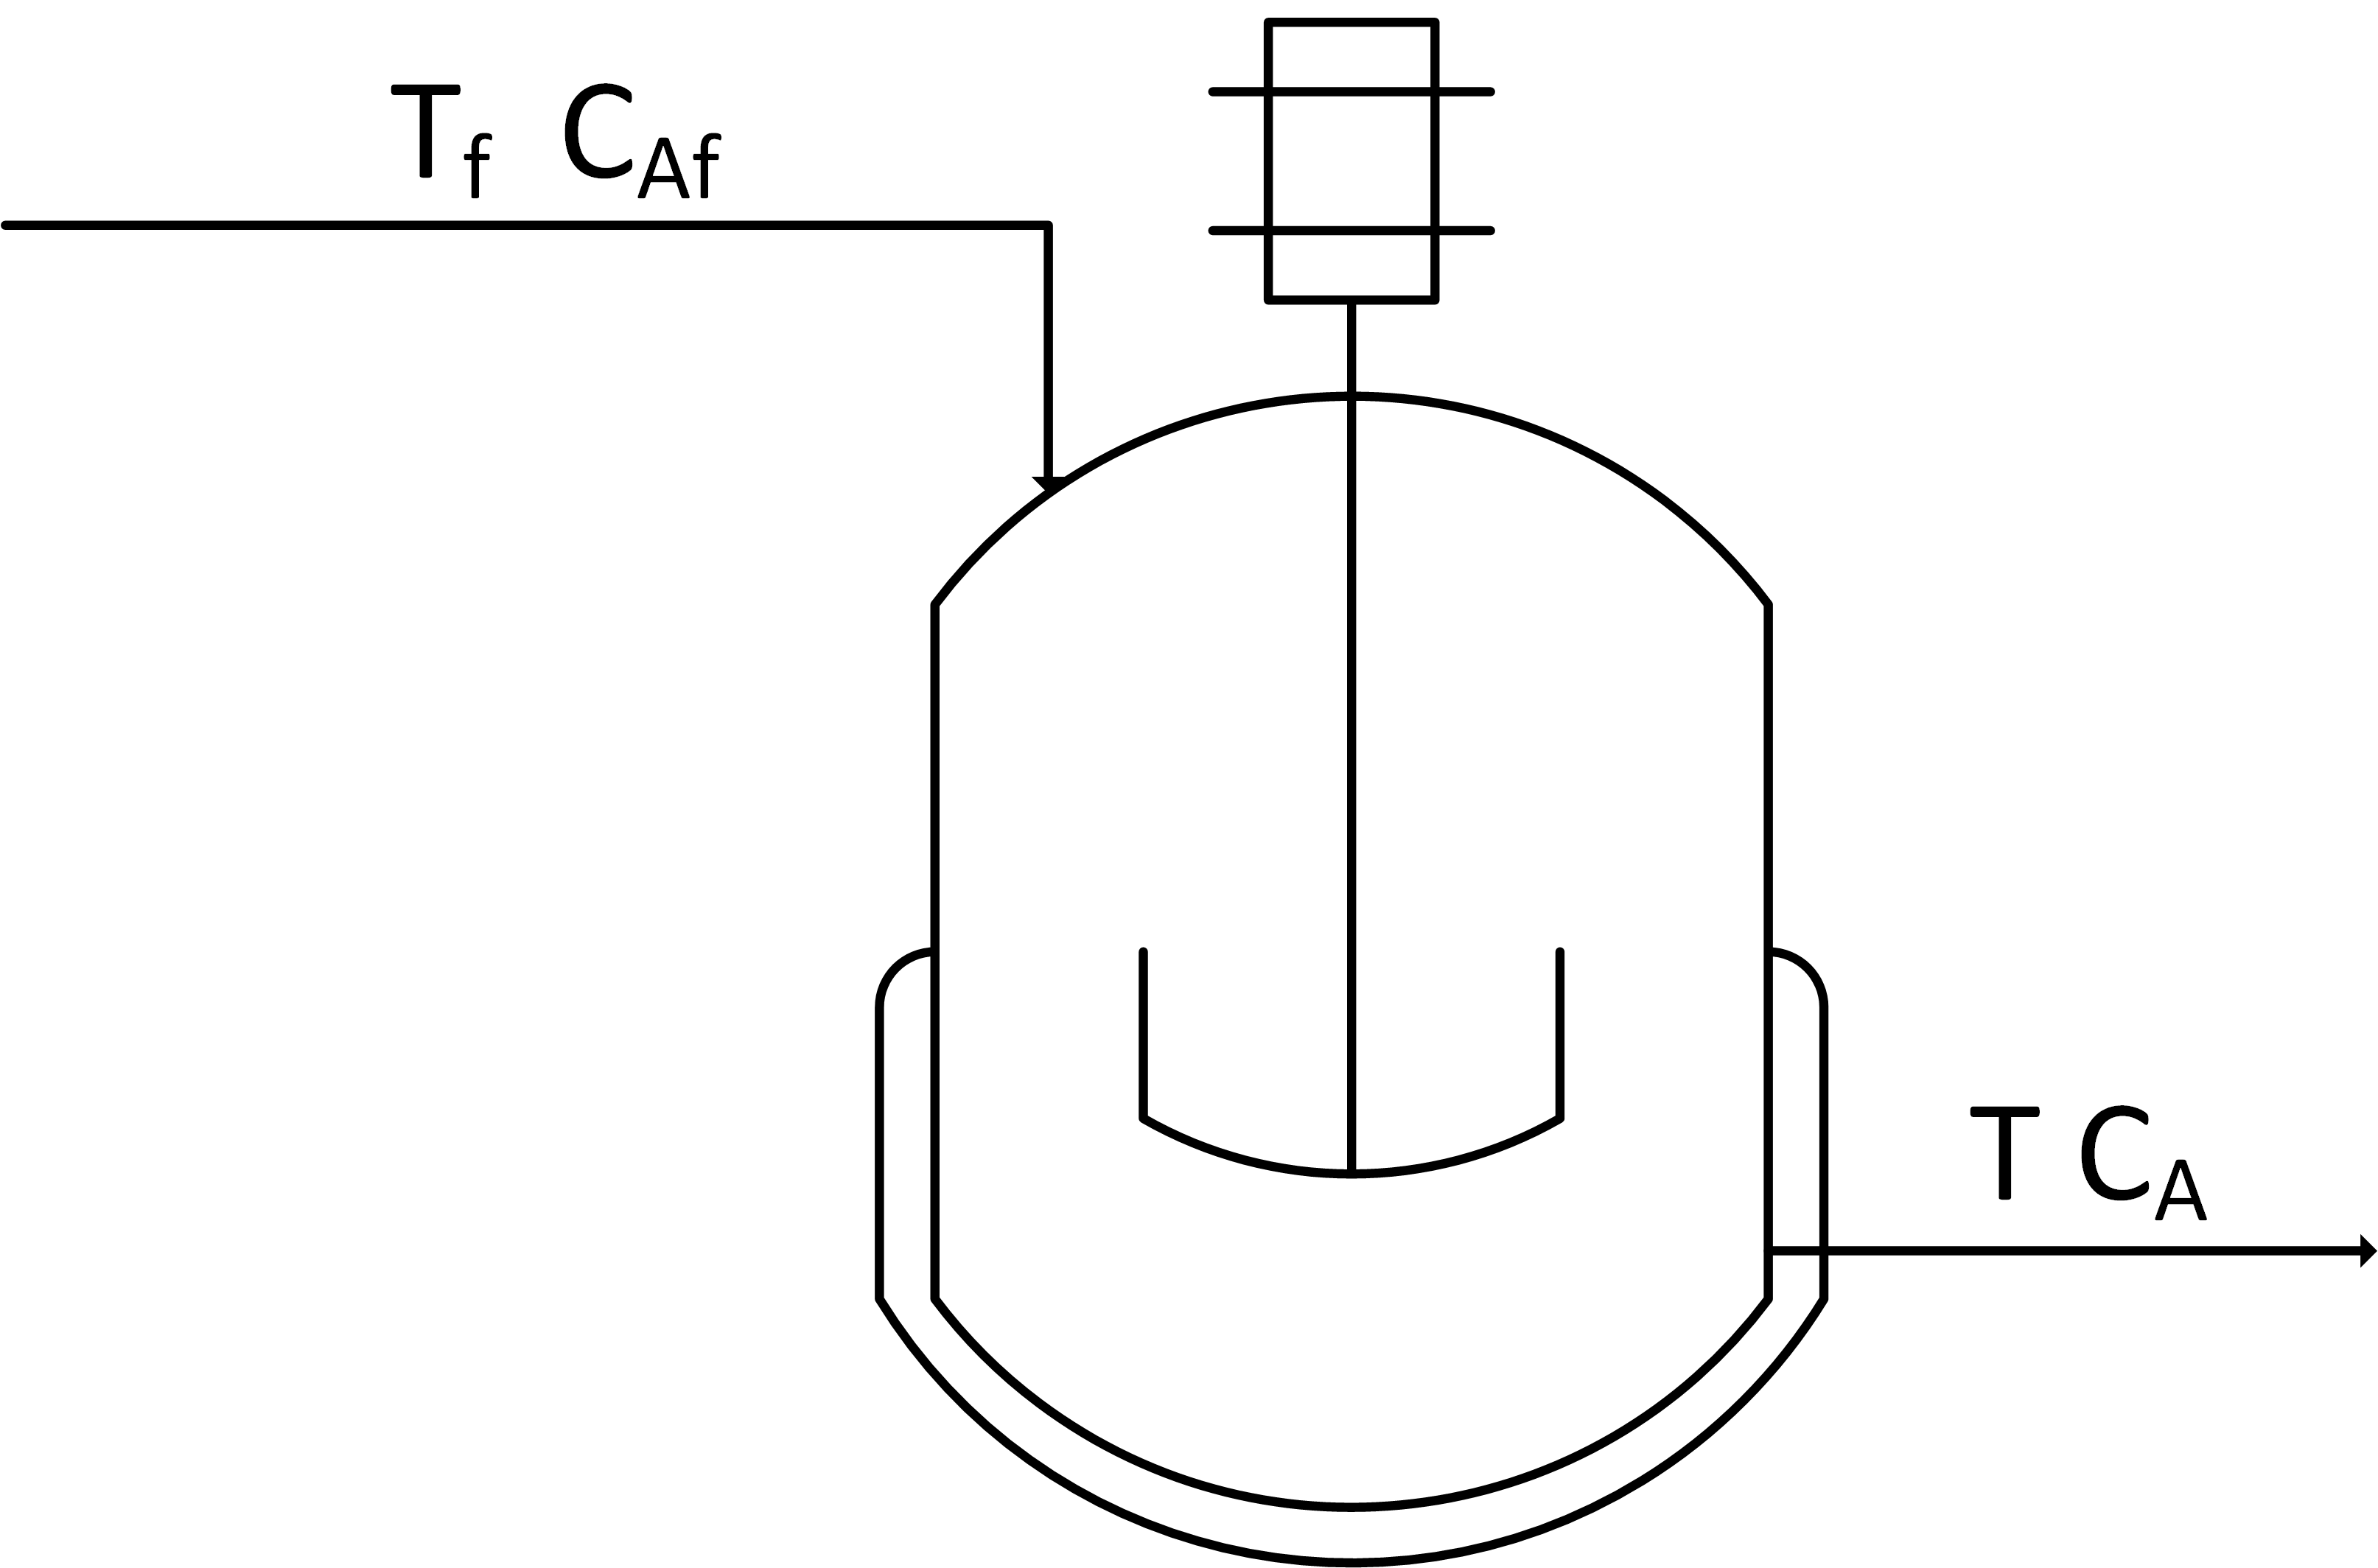

A prior exercise involves starting with species and energy balance equations and deriving the dynamic concentration and temperature response. The derivation of the concentration response is provided below with a constant tank volume *V* of 100 $\text{m}^3$ and an inlet flow rate $\dot{V}$ of 100 $\text{m}^3/\text{hr}$. A species balance is simulated with the accumulation, inlet, and outlet terms of the number of moles *n* of species *A*. The accumulation of *A*, *d(*$n_A$*)/dt*, in a control volume is calculated by inlet, outlet, reaction generation, and reaction consumption rates.


$$\frac{dn_A}{dt} = \sum{\dot{n}_{A_{in}}} - \sum{\dot{n}_{A_{out}}} + \sum{\dot{n}_{A_{gen}}} - \sum{\dot{n}_{A_{cons}}}$$


The molar amount, $n_A$ is often measured as a concentration, $c_A$. In this application there are no reaction terms so the species balance can be simplified.


$$\frac{dc_AV}{dt} = c_{A_{in}}\dot{V}_{in} - c_{A_{out}}\dot{V}_{out}$$


## Exercise: Implement PID Control

viewSolution(false)

Implement a **PID controller** that maintains the outlet concentration of *A* in the mixer by automatically adjusting the feed concentration. Assume that the concentration is continuously measured and that the controller should be designed to follow set point changes to 1.5 mol/L and then down to 1.0 mol/L. The maximum feed concentration is 2.0 mol/L and the minimum is 0.0 mol/L. Report the PID tuning parameters and show time plots of the dynamic response of the controller.

### Parameters

% Initial Condition
Ca0 = 0.0;
% Feed Temperature (K)
Tf = 300;
% Time Interval (min)
tFinal = 10;
n = 100;
ts = linspace(0,tFinal,n);

### Initialize Storage Arrays

Ca = zeros(n,1);
Ca(1) = Ca0;
Caf = zeros(n,1);
% Error
e = zeros(n,1);
% Set Points
sp = ones(n,1)*1.5;
sp(50:end) = 1.0;

### PID Controller Tuning Parameters

Kc =  ;

Invalid expression. Check for missing or extra characters.

tau_i =  ;
tau_d =  ;
dt = ts(2) - ts(1);
integral=0;

### Simulate Mixer

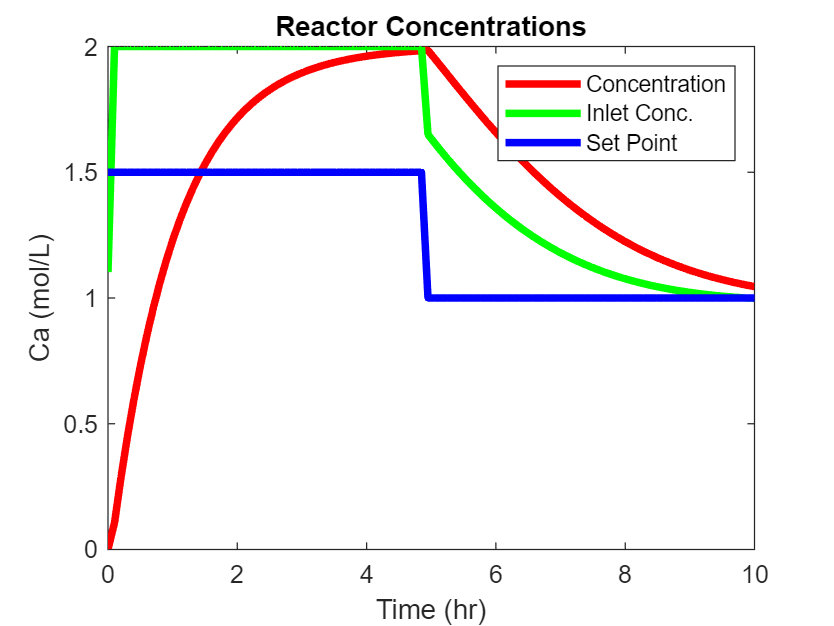

for i = 1:(n-1)
    %Error
    e(i) =  ;
    integral =  ;
    if i >= 2
        deriv =  ;
    else
        deriv = 0;
    end
    Caf(i) =  ;
    %clip bounds of feed
    if Caf(i) > 2.0
        Caf(i) = 2.0;
    elseif Caf(i) < 0.0
        Caf(i) = 0.0;
    end
    
    [t,y] = ode45( );
    Ca0 = y(end);
    Ca(i+1) = Ca0;
end
Caf(end) = Caf(end-1);

% Construct results and save data file
% Column 1 = time
% Column 2 = concentration
data = vertcat(t.',y.');       % vertical stack
data = data.';              % transpose data
writematrix(data,'data.csv');

% Plot the results
plot(ts,Ca,'r-','LineWidth',3); hold on
plot(ts,Caf,'g-','LineWidth',3);
plot(ts,sp,'b-','LineWidth',3); hold off
ylabel('Ca (mol/L)')
legend({'Concentration','Inlet Conc.', 'Set Point'});
xlabel('Time (hr)');
title('Reactor Concentrations')

### Define the Mixing Model

function dCadt = mixer(~,x,~,Caf)
    % Inputs (2):
    % Tf = Feed Temperature (K)
    % Caf = Feed Concentration (mol/L)
    % States (2):
    % Concentration of A (mol/L)
    Ca = x(1);
    % Parameters:
    % Volumetric Flowrate (m^3/hr)
    q = 100;
    % Volume of CSTR (m^3)
    V = 100;
    % Calculate concentration derivative
    dCadt = q/V*(Caf - Ca);
end


### Solution

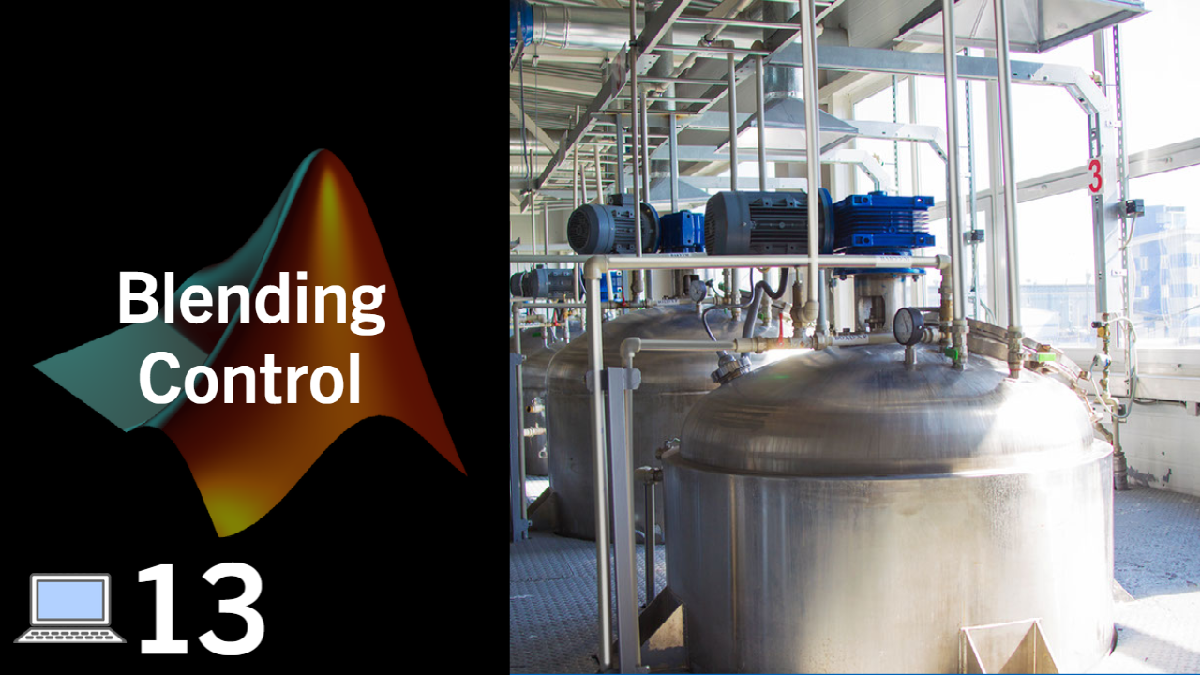

### [View Screencast](https://youtu.be/z1Si-bMFaGE)

function viewSolution(view)
if view
	disp("% PID Controller Tuning Parameters" + newline + ...
	     "Kc = 0.7;" + newline + ...
	     "tau_i = 2.0;" + newline + ...
	     "tau_d = 0.1;" + newline + ...
	     "dt = ts(2) - ts(1);" + newline + ...
	     "integral=0;" + newline + ...
	     "" + newline + ...
	     "" + newline + ...
	     "% Simulate Mixer" + newline + ...
	     "for i = 1:(n-1)" + newline + ...
	     "    %Error" + newline + ...
	     "    e(i) = sp(i) - Ca(i);" + newline + ...
	     "    integral = integral + e(i)*dt;" + newline + ...
	     "    if i >= 2" + newline + ...
	     "        deriv = (Ca(i+1) - Ca(i))/dt;" + newline + ...
	     "    else" + newline + ...
	     "        deriv = 0;" + newline + ...
	     "    end" + newline + ...
	     "    Caf(i) = Caf(1) + Kc*e(i) + Kc/tau_i*integral - Kc*tau_d*deriv;" + newline + ...
	     "    %clip bounds of feed" + newline + ...
	     "    if Caf(i) > 2.0" + newline + ...
	     "        Caf(i) = 2.0;" + newline + ...
	     "    elseif Caf(i) < 0.0" + newline + ...
	     "        Caf(i) = 0.0;" + newline + ...
	     "    end" + newline + ...
	     "    " + newline + ...
	     "    [t,y] = ode45(@(t,y) mixer(t,y,Tf,Caf(i)), [ts(i) ts(i+1)], Ca0);" + newline + ...
	     "    Ca0 = y(end);" + newline + ...
	     "    Ca(i+1) = Ca0;" + newline + ...
	     "end" + newline + ...
	     "Caf(end) = Caf(end-1);" + newline + ...
	     "" + newline + ...
	     "% Construct results and save data file" + newline + ...
	     "% Column 1 = time" + newline + ...
	     "% Column 2 = concentration" + newline + ...
	     "data = vertcat(t.',y.');       % vertical stack" + newline + ...
	     "data = data.';              % transpose data" + newline + ...
	     "writematrix(data,'data.csv');" + newline + ...
	     "" + newline + ...
	     "% Plot the results" + newline + ...
	     "plot(ts,Ca,'r-','LineWidth',3); hold on" + newline + ...
	     "plot(ts,Caf,'g-','LineWidth',3);" + newline + ...
	     "plot(ts,sp,'b-','LineWidth',3); hold off" + newline + ...
	     "ylabel('Ca (mol/L)')" + newline + ...
	     "legend({'Concentration','Inlet Conc.', 'Set Point'});" + newline + ...
	     "xlabel('Time (hr)');" + newline + ...
	 "end")
end
end